# Lab 6

## Exercise 1

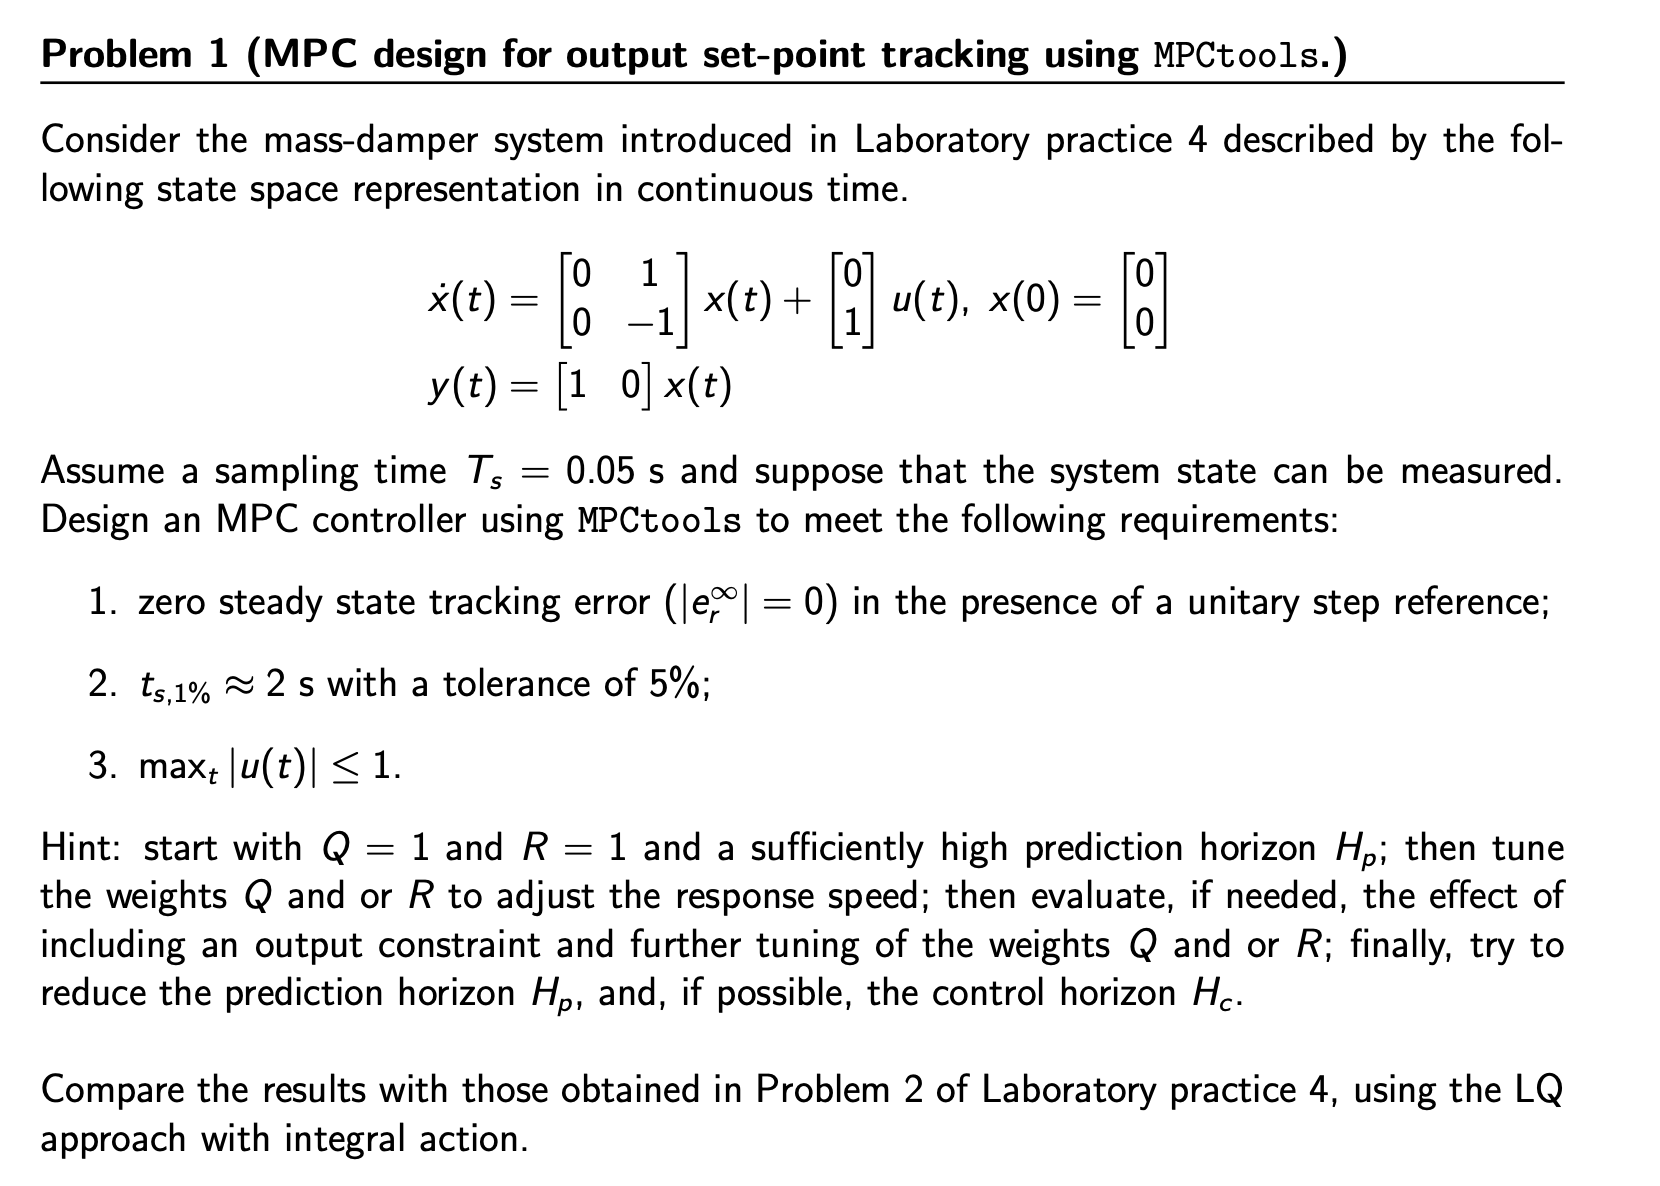

close all
clear
clc

A = [0 1; 0 -1];
B = [0;1];
C = [1 0];
D = 0;
x0 = [0; 0];

Ts = 0.05;

sys = ss(A,B,C,D);

sys_dt = c2d(sys,Ts, 'zoh');

Ad = sys_dt.a;
Bd = sys_dt.b;
Cd = sys_dt.c;
Dd = sys_dt.d;

sys_x = ss(A,B,eye(2),0); 



#### Definining MPCtools elements

Cy = eye(2); % the output measured is the state => C must be eye
Cz = Cd; Dz = 0; % controlled output
Cc = Cd; Dc = 0; % constrained output = controlled output
Q = 1;
R = 1;
cmode = 0; % state feedback mode
h = Ts;
z_max = [inf]; % output constraints (no constraints but we need to define these limitations)
z_min = [-inf]; 
u_max = [1]; % input constraints
u_min = [-1]; 
du_max = [inf]; % rate constraints
du_min = [-inf]; 

% Hp must be around 45 in order to predict at least settling time time interval
Hp = 45;
Hu = Hp;
Hw = 1; % first penalty sample 
z_blk = 1; % no blocking
u_blk = 1; % no blocking

#### Compute MPC controller

md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk, Hu,u_blk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h, cmode, ...
    'qp_as');

Setting up matrices...
Preparing matrix setup...
Building prediction matrices...
Post-creation matrix operations...


#### Simulation 

t_sim = 5;
rho = 1;
out = sim('sim_mpc.slx');

Update start, t=0.00
Update start, t=0.05
Update start, t=0.10
Update start, t=0.15
Update start, t=0.20
Update start, t=0.25
Update start, t=0.30
Update start, t=0.35
Update start, t=0.40
Update start, t=0.45
Update start, t=0.50
Update start, t=0.55
Update start, t=0.60
Update start, t=0.65
Update start, t=0.70
Update start, t=0.75
Update start, t=0.80
Update start, t=0.85
Update start, t=0.90
Update start, t=0.95
Update start, t=1.00
Update start, t=1.05
Update start, t=1.10
Update start, t=1.15
Update start, t=1.20
Update start, t=1.25
Update start, t=1.30
Update start, t=1.35
Update start, t=1.40
Update start, t=1.45
Update start, t=1.50
Update start, t=1.55
Update start, t=1.60
Update start, t=1.65
Update start, t=1.70
Update start, t=1.75
Update start, t=1.80
Update start, t=1.85
Update start, t=1.90
Update start, t=1.95
Update start, t=2.00
Update start, t=2.05
Update start, t=2.10
Update start, t=2.15
Update start, t=2.20
Update start, t=2.25
Update start, t=2.30
Update start,

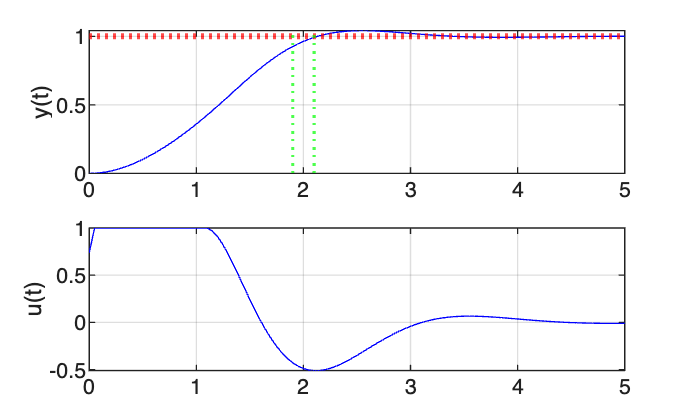

figure
subplot(211)
plot(out.y.time,out.y.data,'b');
yline(rho*1.01, ':r', 'LineWidth',1.2)
yline(rho*0.99, ':r', 'LineWidth',1.2)
xline(2*1.05, ':g', 'LineWidth',1.2)
xline(2*0.95, ':g', 'LineWidth',1.2)
hold on
grid on
ylabel('y(t)')
subplot(212)
plot(out.u.time,out.u.data,'b');
hold on
grid on
ylabel('u(t)')

### Tuning

Since our response is "too slow" for our requirements, we need  to increase Q or add output limitations. We implement, for the meme, both solutions

Q = 10;

z_max = [1.01]; 
z_min = [-inf];

md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk, Hu,u_blk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h, cmode, ...
    'qp_as');

Setting up matrices...
Preparing matrix setup...
Building prediction matrices...
Post-creation matrix operations...



clear out

out = sim('sim_mpc.slx');

Update start, t=0.00
Update start, t=0.05
Update start, t=0.10
Update start, t=0.15
Update start, t=0.20
Update start, t=0.25
Update start, t=0.30
Update start, t=0.35
Update start, t=0.40
Update start, t=0.45
Update start, t=0.50
Update start, t=0.55
Update start, t=0.60
Update start, t=0.65
Update start, t=0.70
Update start, t=0.75
Update start, t=0.80
Update start, t=0.85
Update start, t=0.90
Update start, t=0.95
Update start, t=1.00
Update start, t=1.05
Update start, t=1.10
Update start, t=1.15
Update start, t=1.20
Update start, t=1.25
Update start, t=1.30
Update start, t=1.35
Update start, t=1.40
Update start, t=1.45
Update start, t=1.50
Update start, t=1.55
Update start, t=1.60
Update start, t=1.65
Update start, t=1.70
Update start, t=1.75
Update start, t=1.80
Update start, t=1.85
Update start, t=1.90
Update start, t=1.95
Update start, t=2.00
Update start, t=2.05
Update start, t=2.10
Update start, t=2.15
Update start, t=2.20
Update start, t=2.25
Update start, t=2.30
Update start,

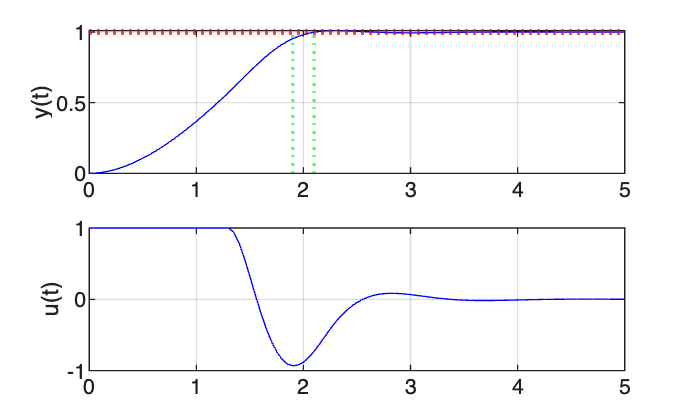

figure
subplot(211)
plot(out.y.time,out.y.data,'b');
yline(rho*1.01, ':r', 'LineWidth',1.2)
yline(rho*0.99, ':r', 'LineWidth',1.2)
xline(2*1.05, ':g', 'LineWidth',1.2)
xline(2*0.95, ':g', 'LineWidth',1.2)
hold on
grid on
ylabel('y(t)')
subplot(212)
plot(out.u.time,out.u.data,'b');
hold on
grid on
ylabel('u(t)')

Now we work on Hp and Hc 

We can reduce Hp = 40 but we can't go further decreasing 

Then we can decrease Hu and see until response is still good

Hp = 40;
Hu = 13;

md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk, Hu,u_blk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h, cmode, ...
    'qp_as');

Setting up matrices...
Preparing matrix setup...
Building prediction matrices...
Post-creation matrix operations...



clear out

out = sim('sim_mpc.slx');

Update start, t=0.00
Update start, t=0.05
Update start, t=0.10
Update start, t=0.15
Update start, t=0.20
Update start, t=0.25
Update start, t=0.30
Update start, t=0.35
Update start, t=0.40
Update start, t=0.45
Update start, t=0.50
Update start, t=0.55
Update start, t=0.60
Update start, t=0.65
Update start, t=0.70
Update start, t=0.75
Update start, t=0.80
Update start, t=0.85
Update start, t=0.90
Update start, t=0.95
Update start, t=1.00
Update start, t=1.05
Update start, t=1.10
Update start, t=1.15
Update start, t=1.20
Update start, t=1.25
Update start, t=1.30
Update start, t=1.35
Update start, t=1.40
Update start, t=1.45
Update start, t=1.50
Update start, t=1.55
Update start, t=1.60
Update start, t=1.65
Update start, t=1.70
Update start, t=1.75
Update start, t=1.80
Update start, t=1.85
Update start, t=1.90
Update start, t=1.95
Update start, t=2.00
Update start, t=2.05
Update start, t=2.10
Update start, t=2.15
Update start, t=2.20
Update start, t=2.25
Update start, t=2.30
Update start,

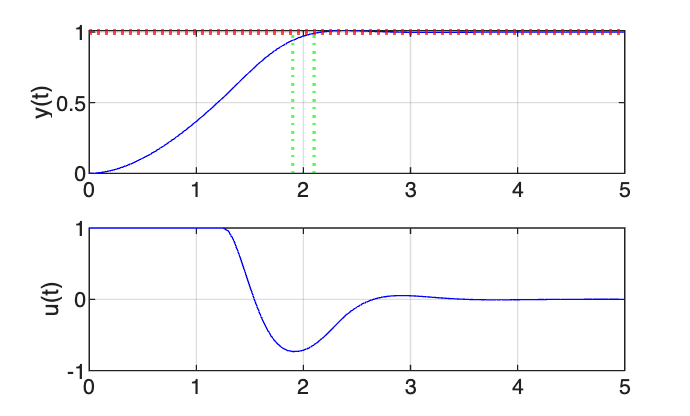

figure
subplot(211)
plot(out.y.time,out.y.data,'b');
yline(rho*1.01, ':r', 'LineWidth',1.2)
yline(rho*0.99, ':r', 'LineWidth',1.2)
xline(2*1.05, ':g', 'LineWidth',1.2)
xline(2*0.95, ':g', 'LineWidth',1.2)
hold on
grid on
ylabel('y(t)')
subplot(212)
plot(out.u.time,out.u.data,'b');
hold on
grid on
ylabel('u(t)')

## Exercise 2

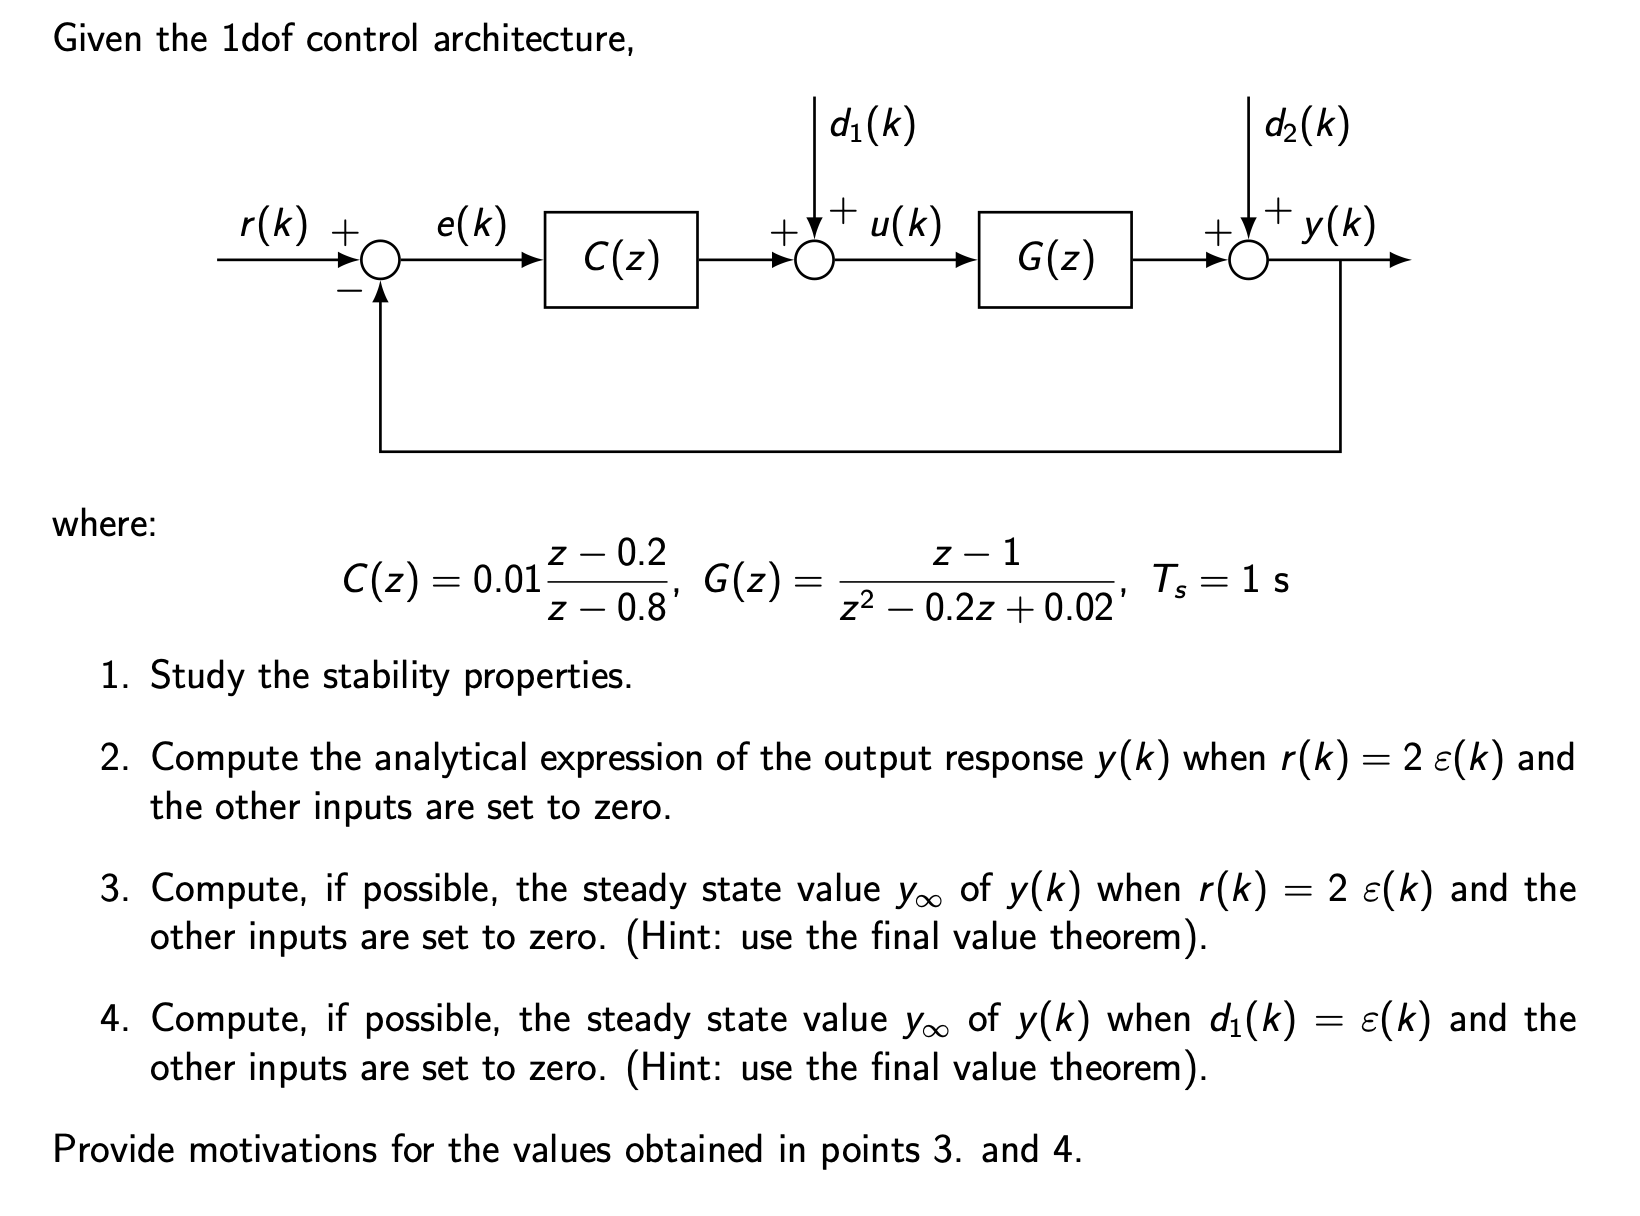

close all
clear
clc

Ts = 1;
z = tf('z',Ts);
G = (z-1)/(z^2-0.2*z+0.02);
C = 0.01*(z-0.2)/(z-0.8);
zpk(G)


ans =
 
         (z-1)
  -------------------
  (z^2 - 0.2z + 0.02)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


zpk(C)


ans =
 
  0.01 (z-0.2)
  ------------
    (z-0.8)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


L = zpk(C*G)


L =
 
      0.01 (z-1) (z-0.2)
  ---------------------------
  (z-0.8) (z^2 - 0.2z + 0.02)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


In order to study the stability, since there are no z-p cancellations, we can check just one of the transfer functions (W, W1, W2, W3)

We can check stability on W

W = zpk(minreal(feedback(L,1),1e-2));
pW = pole(W)

pW =    0.8024 + 0.0000i
   0.0938 + 0.0930i
   0.0938 - 0.0930i


We see that all W poles are stable

### Computing responses

#### Y due to R

The transfer function that links Y to R is W(z)

r = 2*z/(z-1);
Yr = zpk(minreal(W*r,1e-2));
[nYr, dYr] = tfdata(Yr(1), 'v');
[rYr, pYr, kYr] = residuez(nYr, dYr)

rYr =    0.0236 + 0.0000i
  -0.0118 - 0.0177i
  -0.0118 + 0.0177i


pYr =    0.8024 + 0.0000i
   0.0938 + 0.0930i
   0.0938 - 0.0930i


kYr = 0

since we got 2 poles and 2 zeros complex conjugate, we have to express the solution in terms of sinusoidal functions

The analytical passages are:

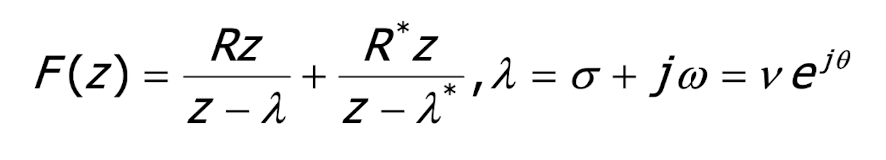

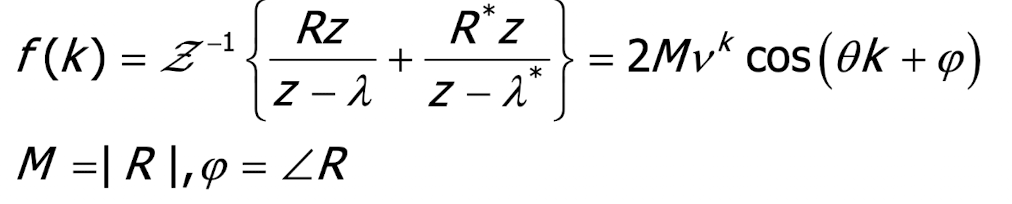

% with our data:
nu = abs(pYr(2))

nu = 0.1321

theta = angle(pYr(2))

theta = 0.7810

M = abs(rYr(2));
M2 = 2*M

M2 = 0.0425

phi = angle(rYr(2))

phi = -2.1596


% Y_inf -> lim_{z->1} (z-1)*Y(z)
Y_inf = dcgain(minreal((z-1)*Yr,1e-2))

Y_inf = 0

#### Y due to D1

The transfer function that links Y to D1 is W1(z)

d1 = z/(z-1);
W1 = G/(1+L);
Yd1 = W*d1;

% Y_inf -> lim_{z->1} (z-1)*Y(z)
Y_inf = dcgain(minreal((z-1)*Yd1,1e-2))

Y_inf = 1.6247e-17

## Exercise 3

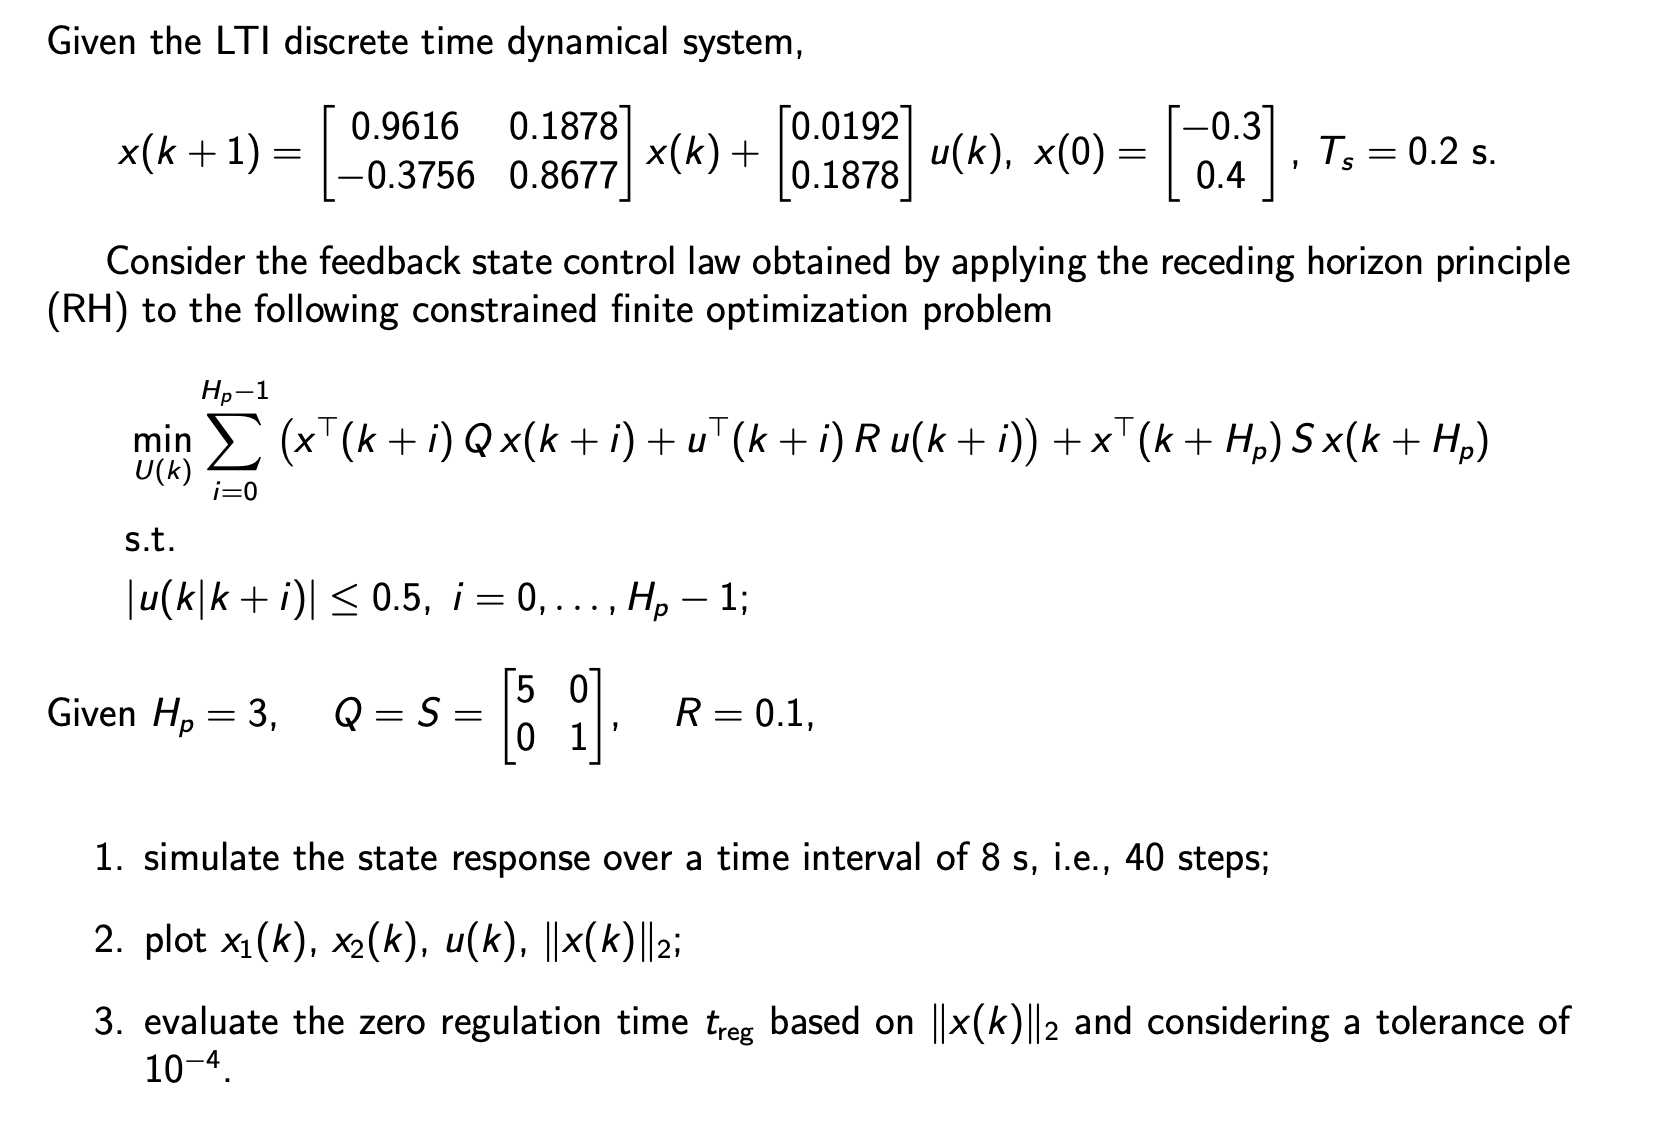

close all
clear
clc

A = [0.9616 0.1878; -0.3756 0.8677];
B = [0.0192; 0.1878];
x0 = [-0.3; 0.4];
Ts = 0.2;
Hp = 3;
Q = [5 0; 0 1];
S = Q;
R = 0.1;

% building cal system
[A_cal, B_cal, Q_cal, R_cal] = cal_m_builder(Hp, A, B, R, Q, S);
H = 2*(B_cal'*Q_cal*B_cal+R_cal);
F = 2*A_cal'*Q_cal*B_cal;

F =     0.6378   -0.0077   -0.2115
    1.2366    0.7128    0.2620



x_k = x0;
steps = 40;

G = [eye(Hp); -eye(Hp)];
u_max = 0.5;
h = u_max*ones(2*Hp,1); % consider both positive and negative saturation limits

H = (H+H')/2; % we force symmetry 
x_traj(:,1) = x0;

for kk=1:steps
    % solve qp
    U = quadprog(H,x_k'*F,G,h);
    % compute state
    x_traj(:,kk+1) = A*x_k + B*U(1);
    % update initial state
    x_k = x_traj(:,end);
    % update input traj
    u_traj(kk) = U(1);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

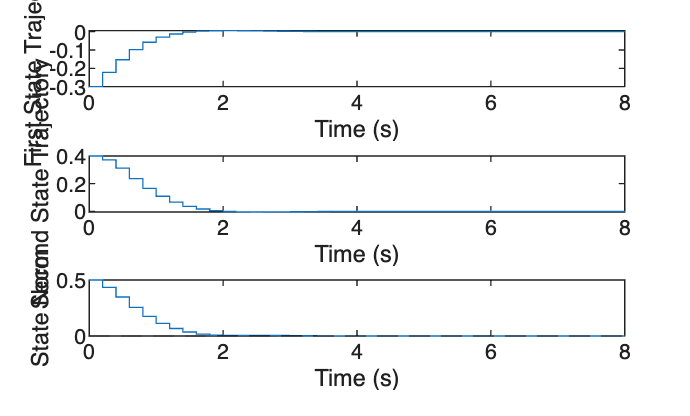



figure
subplot(311)
stairs(0:Ts:steps*Ts, x_traj(1,:))
xlabel('Time (s)')
ylabel('First State Trajectory')

subplot(312)
stairs(0:Ts:steps*Ts, x_traj(2,:))
xlabel('Time (s)')
ylabel('Second State Trajectory')

subplot(313)
stairs(0:Ts:steps*Ts, sqrt(x_traj(1,:).^2 + x_traj(2,:).^2))
xlabel('Time (s)')
ylabel('State Norm')
yline(1e-4, 'k--');

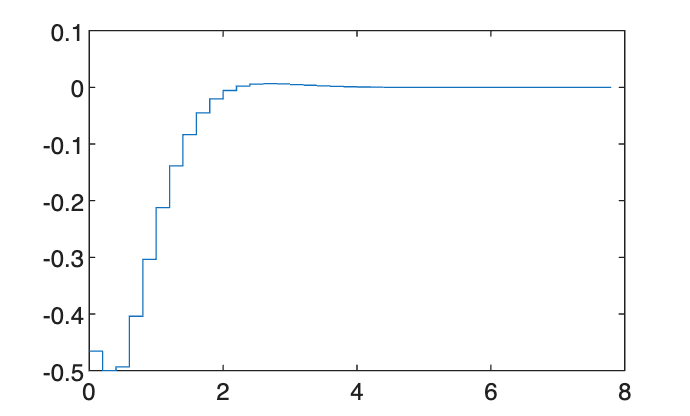


figure
stairs(0:Ts:(steps-1)*Ts, u_traj)

We see from the plot that the state zero regulation requires approx 4.2 seconds

## Exercise 4

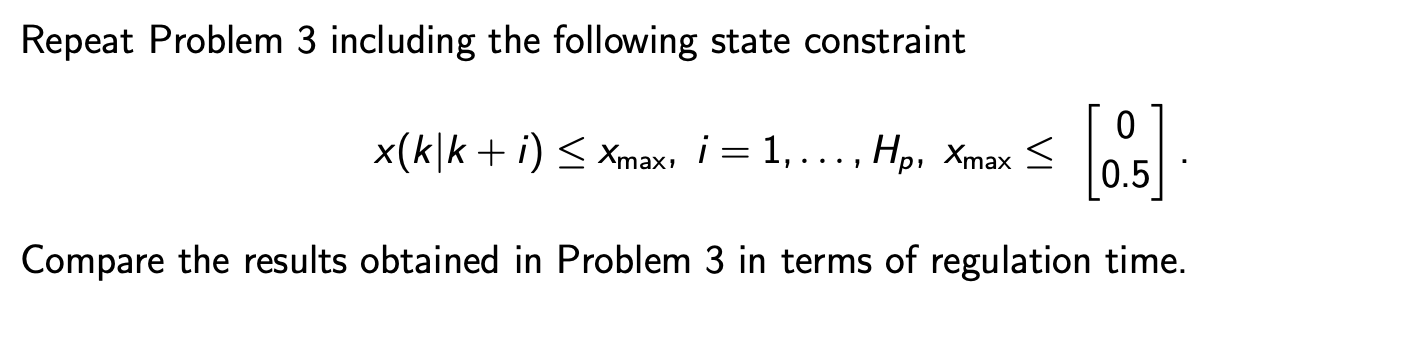

close all
clear
clc

A = [0.9616 0.1878; -0.3756 0.8677];
B = [0.0192; 0.1878];
x0 = [-0.3; 0.4];
Ts = 0.2;
Hp = 3;
Q = [5 0; 0 1];
S = Q;
R = 0.1;

% building cal system
[A_cal, B_cal, Q_cal, R_cal] = cal_m_builder(Hp, A, B, R, Q, S);
H = 2*(B_cal'*Q_cal*B_cal+R_cal);
F = 2*A_cal'*Q_cal*B_cal;

F =     0.6378   -0.0077   -0.2115
    1.2366    0.7128    0.2620



x_k = x0;
steps = 40;

Now we have to change our constraints inequalities in order to include also state constraints

Gu = [eye(Hp); -eye(Hp)];
u_max = 0.5;
hu = u_max*ones(2*Hp,1); % consider both positive and negative saturation limits

Gx = B_cal;
x_max = [0;0.5];
% NOTE: we can't define hx here since it changes at every loop iteration

H = (H+H')/2; % we force symmetry 
x_traj(:,1) = x0;

for kk=1:steps
    % update state constraints
    hx = -A_cal*x_k+repmat(x_max, Hp, 1); % repmat replicates the vector x_max according to a matrix with 3 rows (=Hp) and 1 columns
    
    % let's put constraints together
    G = [Gu;Gx];
    h = [hu;hx];

    % solve qp
    U = quadprog(H,x_k'*F,G,h);
    % compute state
    x_traj(:,kk+1) = A*x_k + B*U(1);
    % update initial state
    x_k = x_traj(:,end);
    % update input traj
    u_traj(kk) = U(1);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

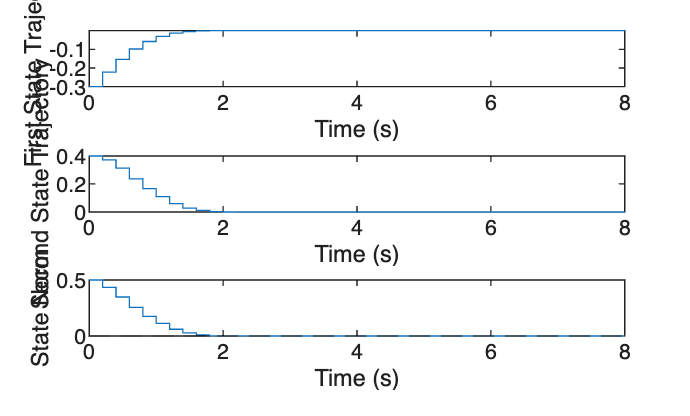


figure
subplot(311)
stairs(0:Ts:steps*Ts, x_traj(1,:))
xlabel('Time (s)')
ylabel('First State Trajectory')

subplot(312)
stairs(0:Ts:steps*Ts, x_traj(2,:))
xlabel('Time (s)')
ylabel('Second State Trajectory')

subplot(313)
stairs(0:Ts:steps*Ts, sqrt(x_traj(1,:).^2 + x_traj(2,:).^2))
xlabel('Time (s)')
ylabel('State Norm')
yline(1e-4, 'k--');

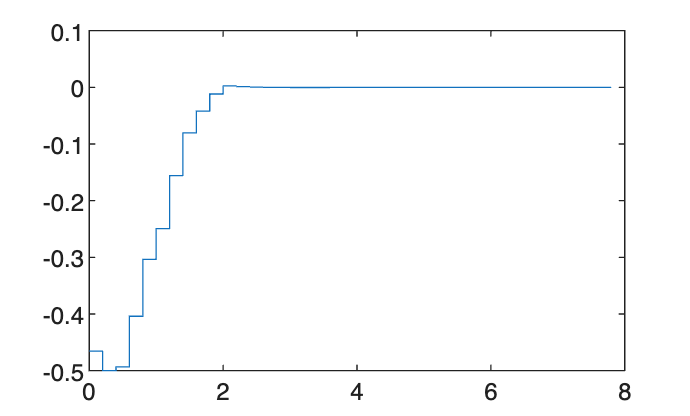


figure
stairs(0:Ts:(steps-1)*Ts, u_traj)

We see from the plot that the state zero regulation requires approx 3.6 seconds